hcube=load('indian_pines_corrected.mat');
hcube=hcube.indian_pines_corrected;

hcube=double(hcube);
hcube=(hcube-min(hcube(:))/(max(hcube(:))-min(hcube(:))))

hcube = hcube(:,:,1) =

   1.0e+03 *

    3.1719    2.5799    3.6869    2.7489    2.7459    2.5749    2.5749    2.5749    2.5779    2.7539    3.8579    2.7459    2.5749    2.5749    2.5749    2.5749    2.5749    2.5749    2.5779    2.7459    2.5699    3.1719    2.5749    2.5699    3.1669    3.0039    2.7459    2.5699    3.1699    3.1699    3.1699    3.1669    3.0019    2.5699    2.9959    3.0039    2.7459    2.5749    2.5779    2.7489    2.7489    2.7459    2.5799    3.6869    2.7459    2.5779    2.7459    2.5749    2.5779    2.7459    2.5749    2.5749    2.5749    2.5799    3.6869    2.7429    3.1719    2.5779    2.7459    2.5779    2.7509    3.6899    3.6899    3.6899    3.6929    3.8579    2.7489    2.7489    2.7429    3.1699    3.1749    2.7459    2.5749    2.5749    2.5699    3.1719    2.5699    3.1669    2.9989    3.1699    3.1619    2.6569    3.1699    3.1669    3.0019    2.5699    3.1719    2.5699    2.9989    3.1699    3.1669    2.9959    2.9989    3.1669    3.0019    2.5699  

[rows,cols,bands]=size(hcube)

rows = 145

cols = 145

bands = 200

figure;
colormap jet;

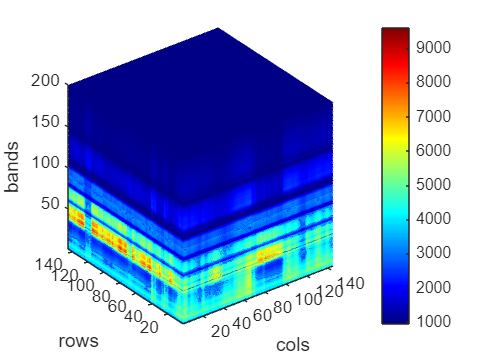

[x,y,z]=meshgrid(1:cols,1:rows,1:bands);
h=slice(x,y,z,hcube,round(cols/2),round(rows/2),1:bands);
set(h,'EdgeColor','none','FaceColor','interp');
xlabel('cols');
ylabel("rows");
zlabel("bands");
colorbar;
view(3);
axis tight;
grid off;